
% Set up directories
% Folder where images are stored
    im_dir='D:\Emi\Saleem lab project\Animal 11\Non-immuno\TIF_images\Slide3\FR';

% Filenames
filename_tif=['Scene_12_farred' '.tif'];
    
% Output filenames
% output_filename_tif='Slide2_slice1_FR.tif';
   

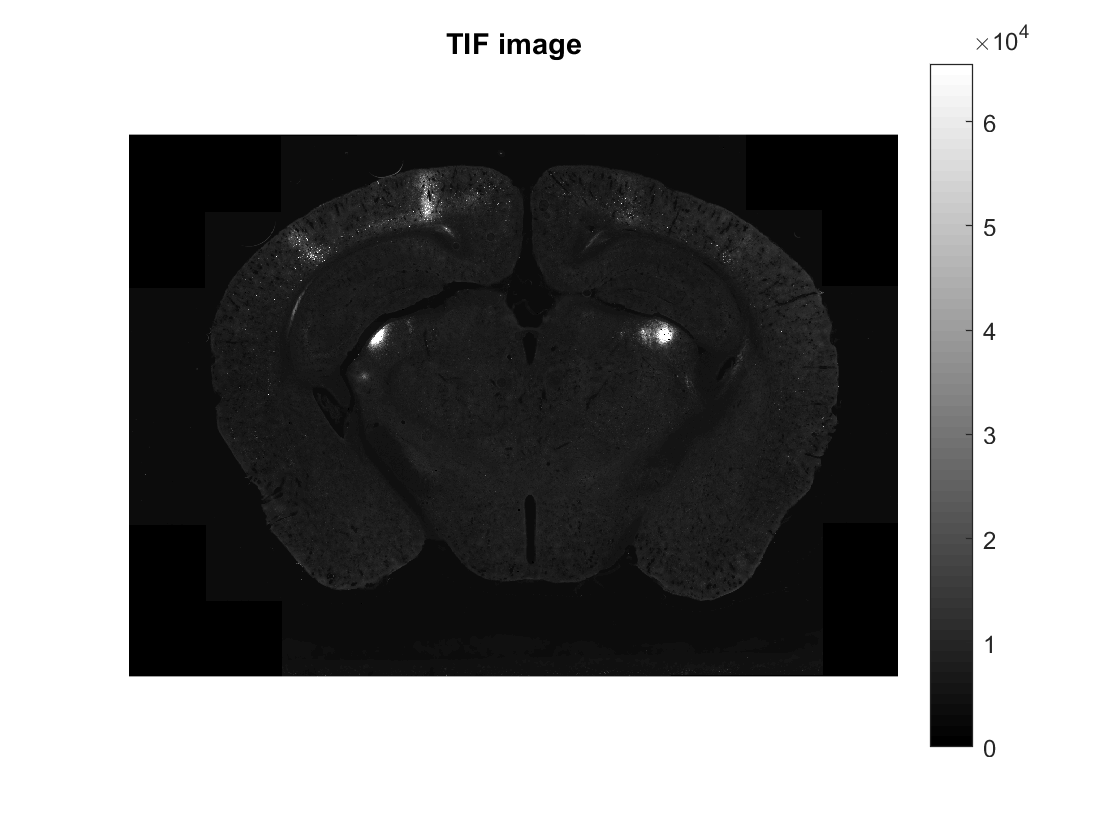

% Load tif image
    InfoImage.tif=imfinfo([im_dir filesep filename_tif]);
    im_tif=zeros(InfoImage.tif.Height,InfoImage.tif.Width,length(InfoImage.tif),'double');

    TifLink = Tiff([im_dir filesep filename_tif], 'r');
    for i=1:length(InfoImage.tif)
       TifLink.setDirectory(i);
       im_tif(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(98);
    imagesc(im_tif)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('TIF image')

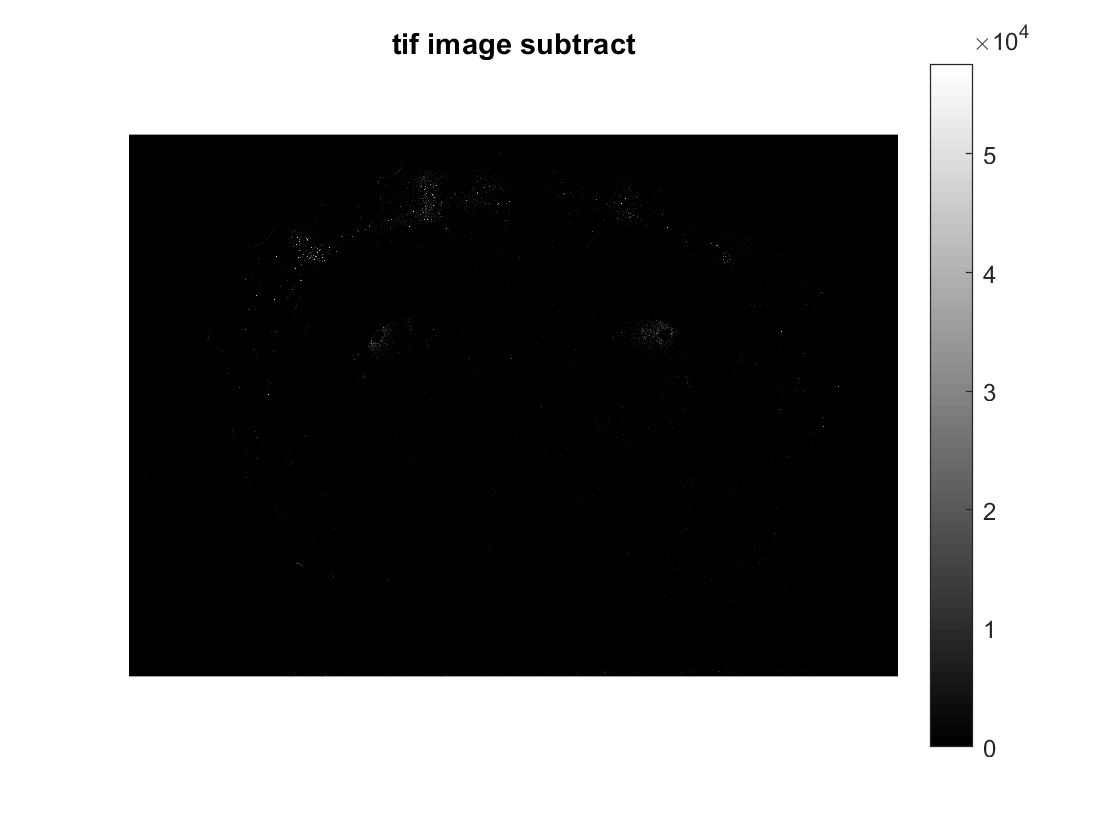

% Background subtraction 
I = im_tif;

im_tif_subtract = imtophat(I,strel('disk',4));
% im_tif_subtract_2 = imadjust(im_tif_subtract,[0.1 0.6])

    figure(100);
    imagesc(im_tif_subtract)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('tif image subtract')

 
 
 im_tif_16bit =uint16(im_tif_subtract);

%  imwrite(im_tif_16bit,[im_dir filesep output_filename_tif]);

level = graythresh(im_tif)

level = 0.4980

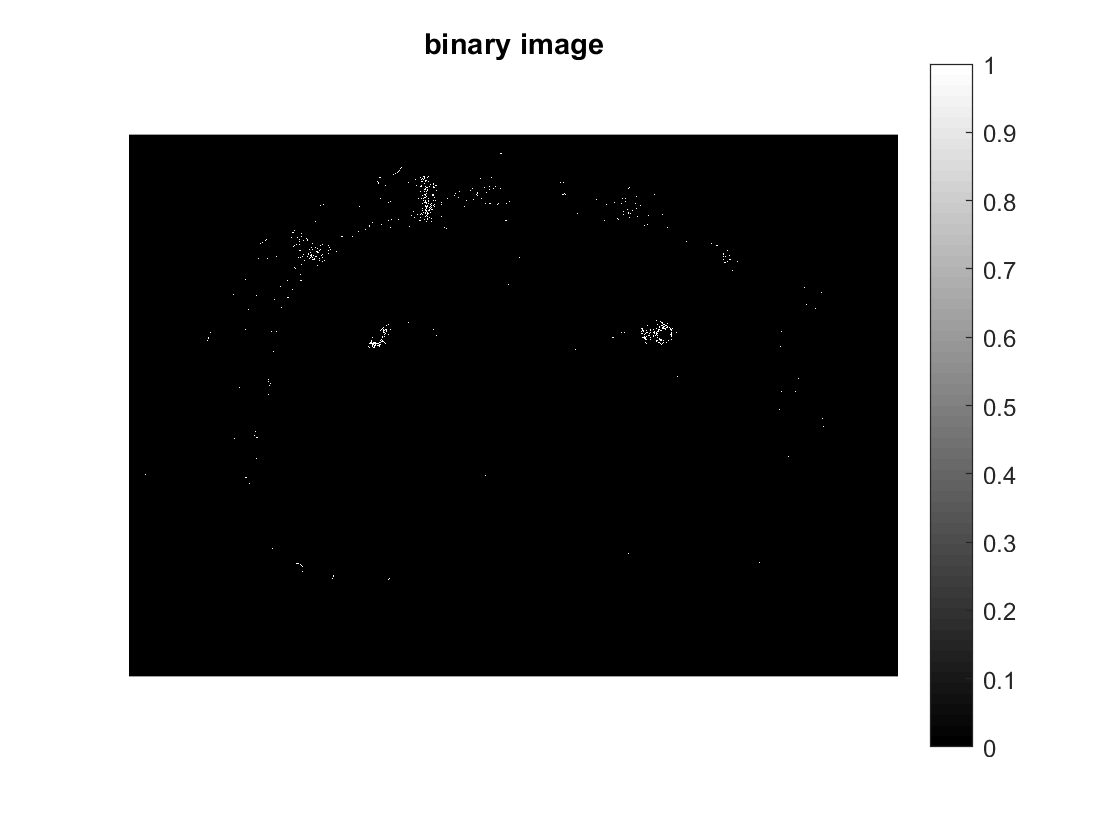

% Thresholding
 im_tif_binary=imbinarize(im_tif_16bit,0.08);

 % Binarize
   im_tif_binary_2=bwareaopen(im_tif_binary,25);
 
   % Filling holes 
%    im_tif_fill=imfill(im_tif_binary,'holes');
%    % Clearing border objects 
%    im_tif_clear=imclearborder(im_tif_fill);
%  
     figure(102);
     imagesc(im_tif_binary_2)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('binary image')

     

im_tif_binary_16bit =uint16(im_tif_binary_2);

%  imwrite(im_tif_binary_16bit,[im_dir filesep output_filename_tif]);


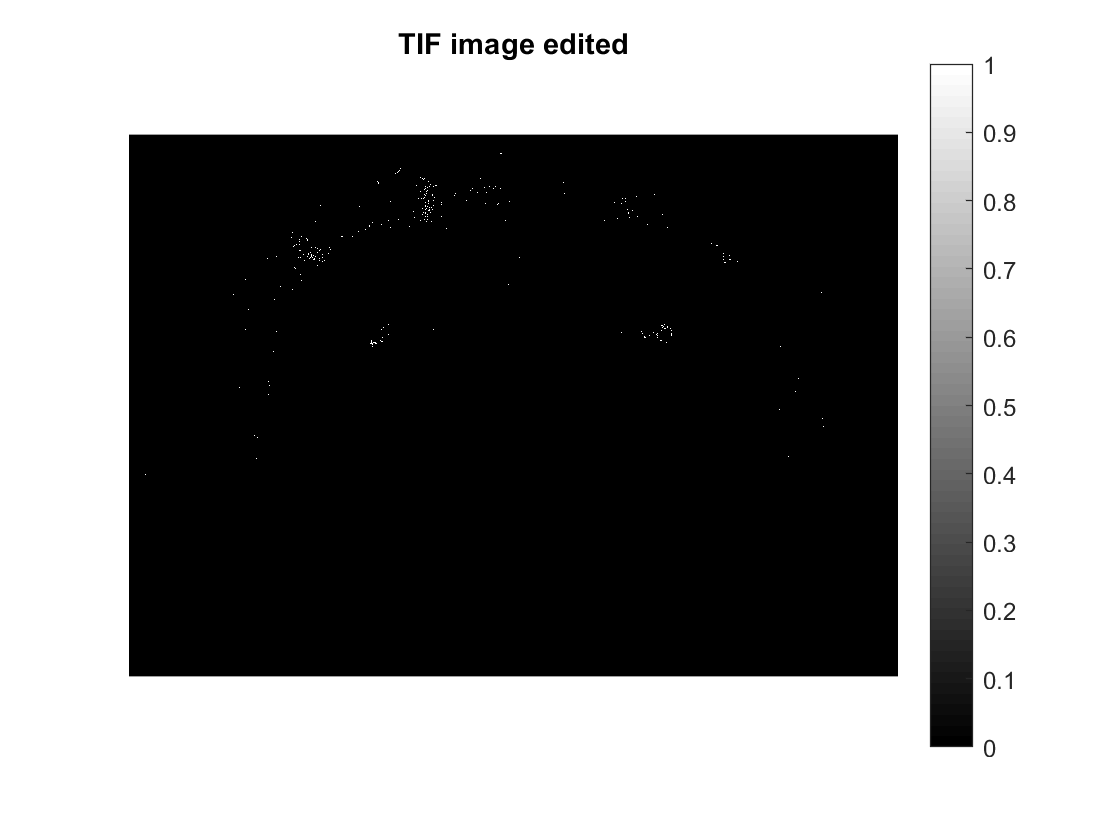

% Erosion and dilation 
se=strel('disk',2);
im_tif_erode=imerode(im_tif_binary_16bit,se);
% se_2=strel('disk',1);
im_tif_dilate=imdilate(im_tif_erode,se);
     
     figure(104);
     imagesc(im_tif_dilate)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('TIF image edited')

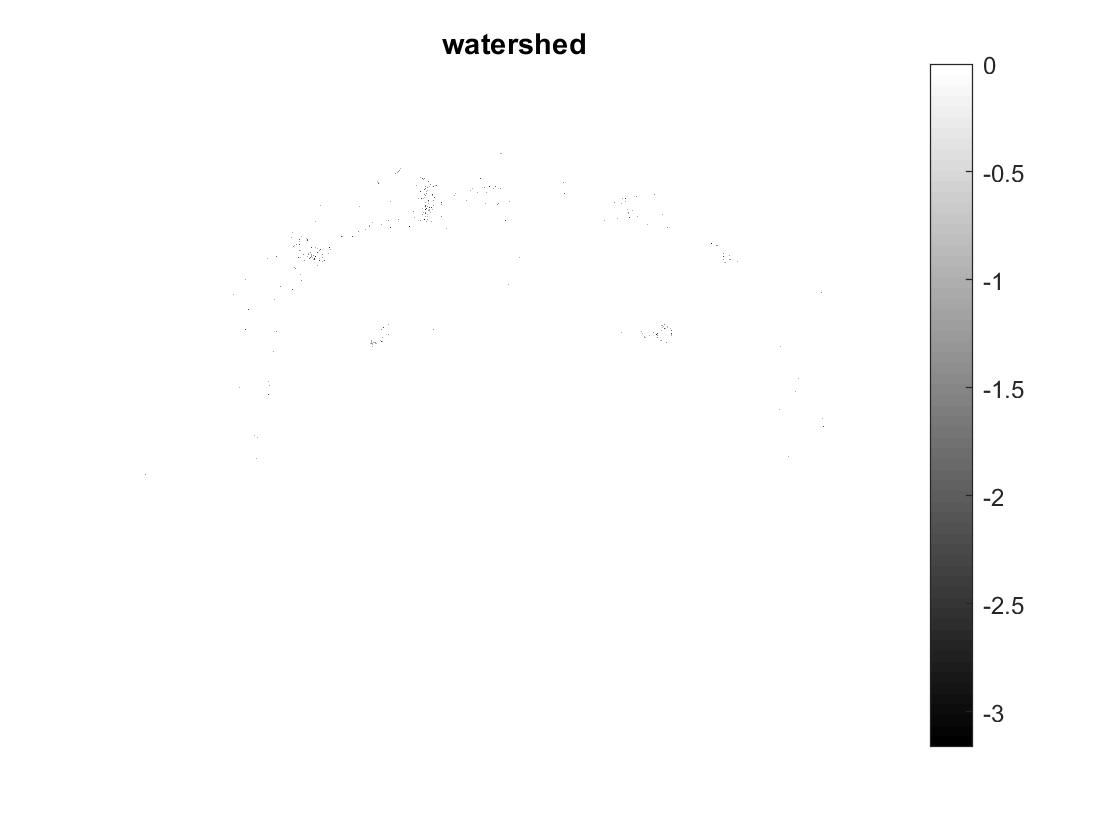

% Watershed
D= -bwdist(~im_tif_dilate);

     figure(105);
     imagesc(D)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('watershed')

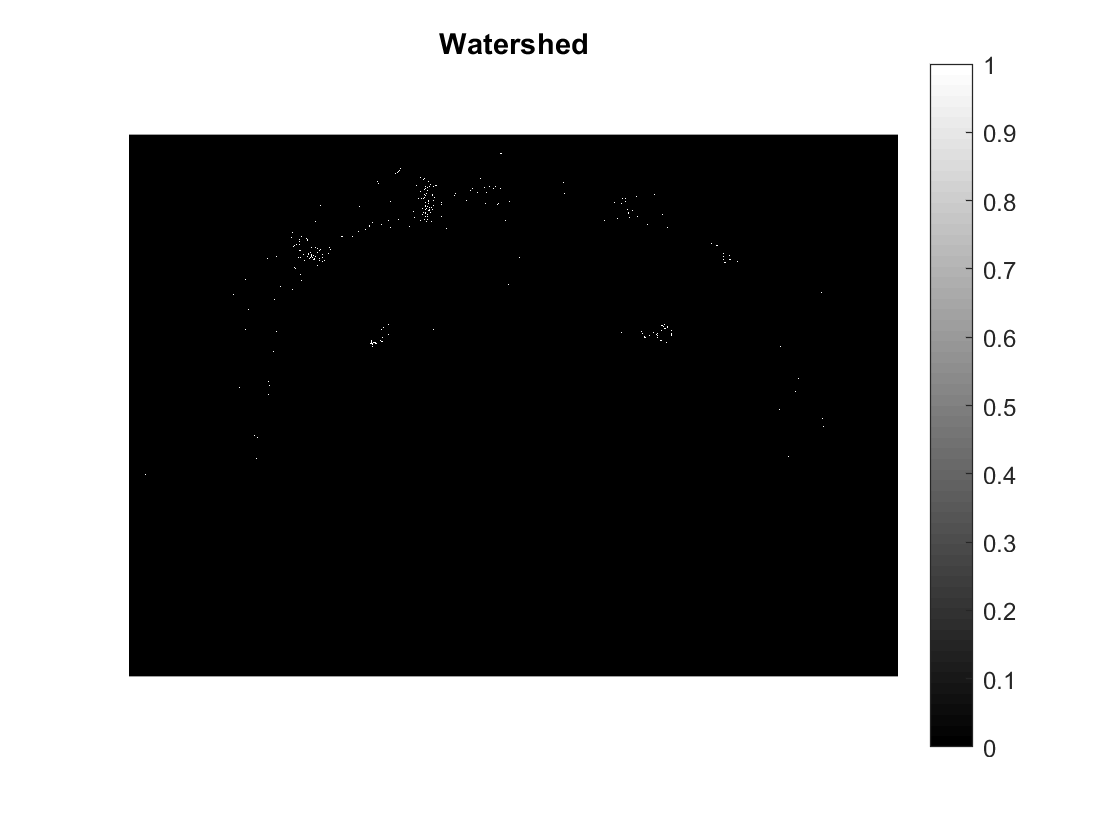

     
im_tif_watershed=watershed(D);
im_tif_dilate_2=im_tif_dilate;
im_tif_dilate_2(im_tif_watershed==0)=0;

     figure(106);
     imagesc(im_tif_dilate_2)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('Watershed')


im_tif_watershed_logical=logical(im_tif_dilate_2);


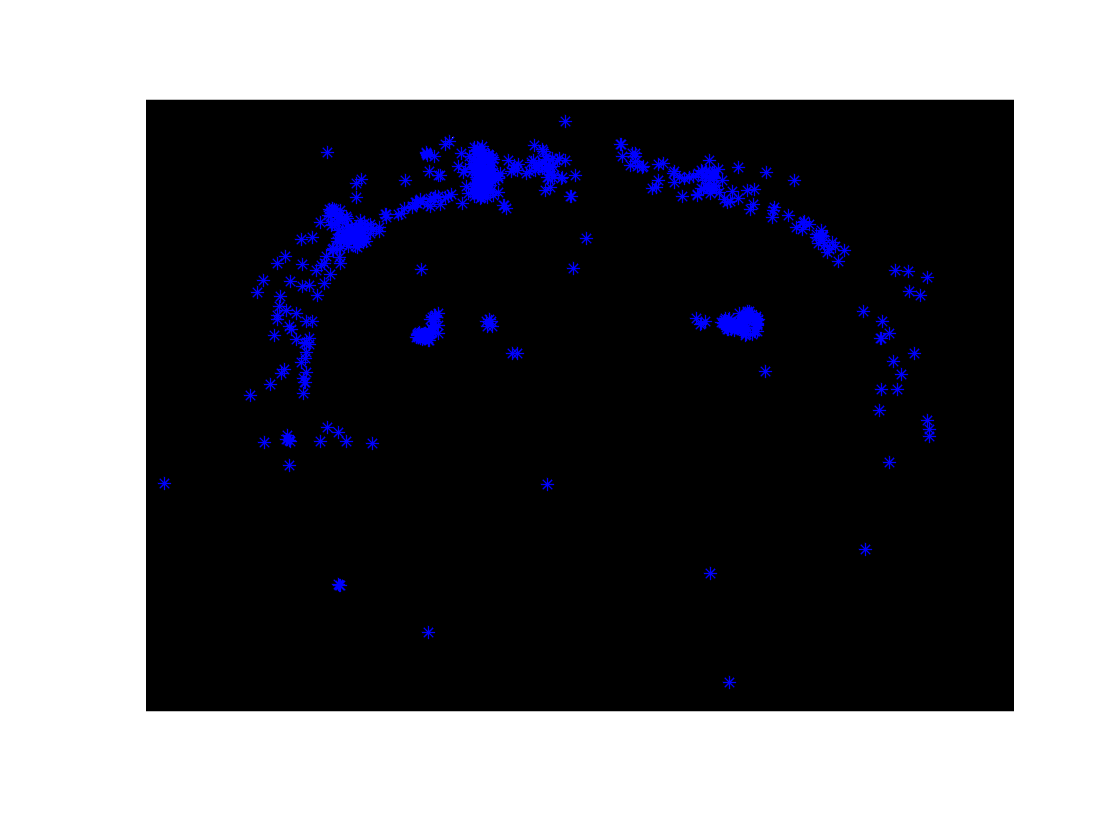

% Obtain centroid coordinates 
cc = bwconncomp(im_tif_watershed_logical); 
stats = regionprops(cc, 'Area','Eccentricity'); 
idx = find([stats.Area] > 10); 
tif_BW2 = ismember(labelmatrix(cc), idx);  

im_tif_XY=regionprops(tif_BW2,'centroid');
centroids = cat(1,im_tif_XY.Centroid);

tif_centroidsX=centroids(1:2:end-1);
tif_centroidsY=centroids(2:2:end);

imshow(im_tif_watershed_logical)
hold on
plot(centroids(:,1),centroids(:,2),'b*','markersize',5)
hold off

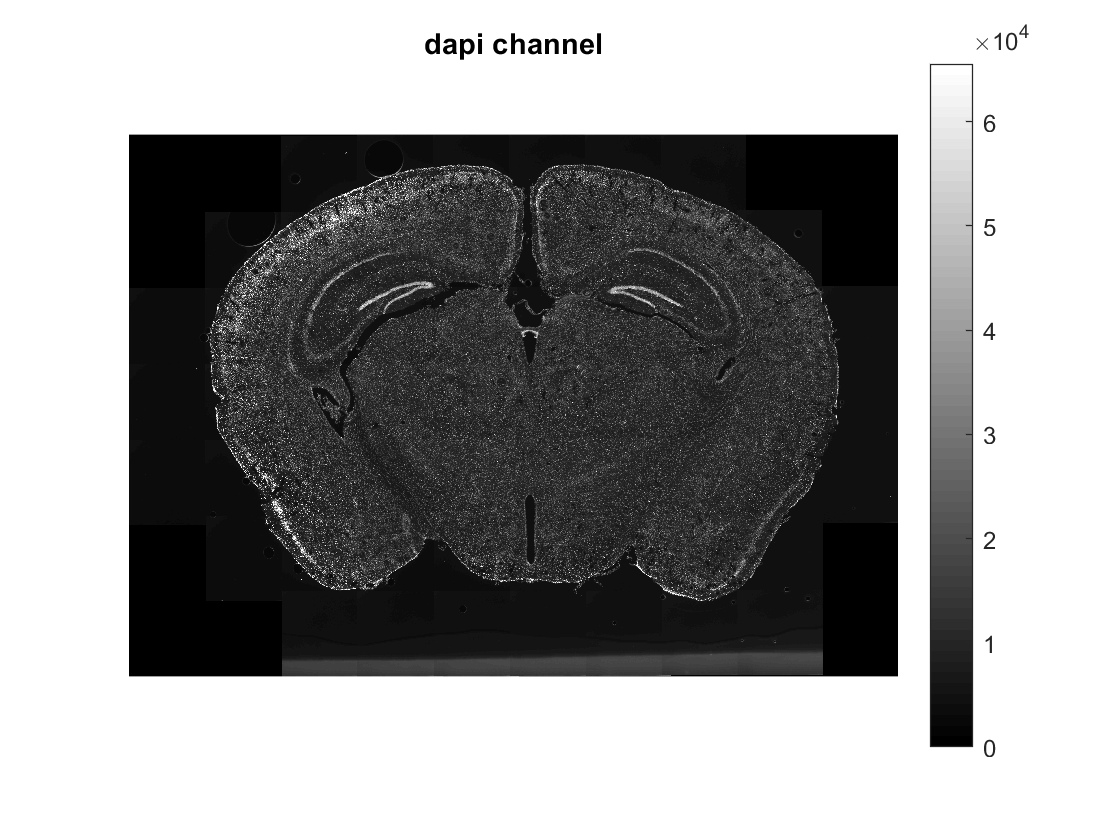

% Load dapi channel
im_dir='D:\Emi\Saleem lab project\Animal 11\Non-immuno\TIF_images\Slide3\Dapi';
filename_dapi='Scene_12.tifdapi.tif';
% output_filename_rgb='Slide2_Slice1_RGB.tif';

InfoImage.dapi=imfinfo([im_dir filesep filename_dapi]);
im_dapi=zeros(InfoImage.dapi.Height,InfoImage.dapi.Width,length(InfoImage.dapi),'double');

    TifLink = Tiff([im_dir filesep filename_dapi], 'r');
    for i=1:length(InfoImage.dapi)
       TifLink.setDirectory(i);
       im_dapi(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure;
    imagesc(im_dapi)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('dapi channel')

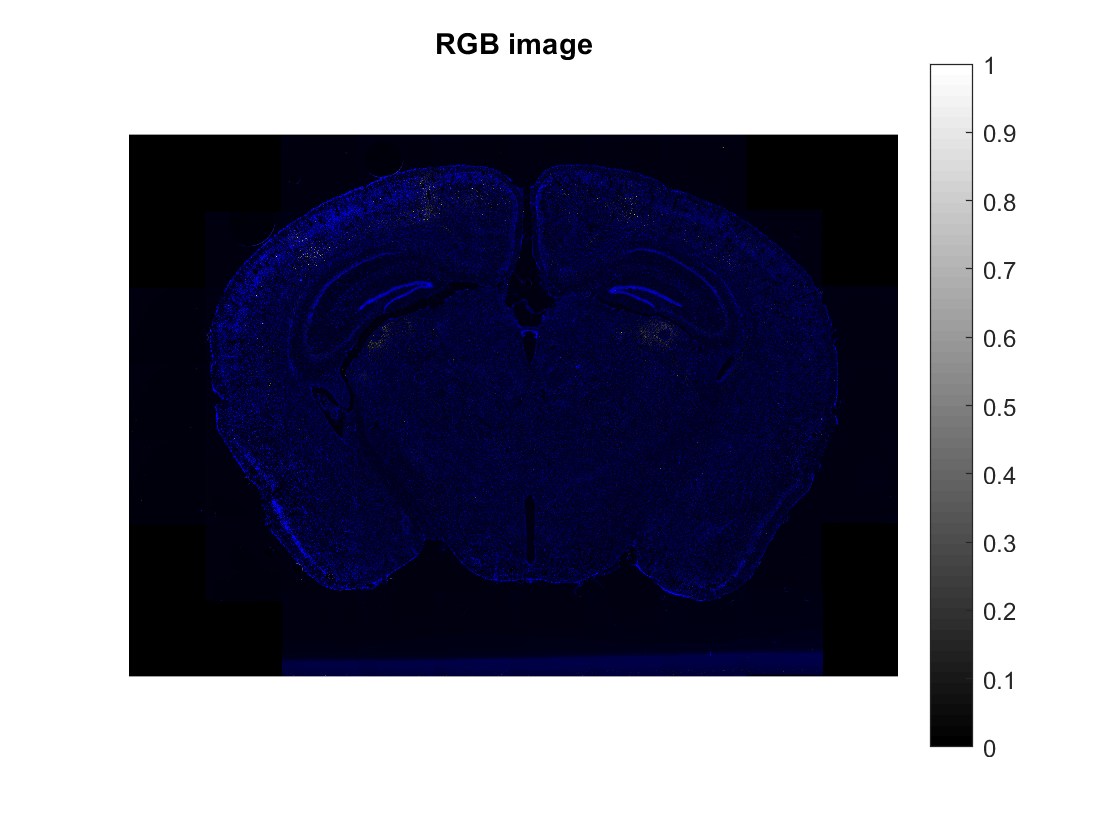

% Combine channels to form RGB 
R=im_tif_16bit;
G=im_tif_16bit;
B=im_dapi;

RGBimage=cat(3,R,G,B);

    figure;
    imagesc(RGBimage)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('RGB image')

    
RGB_uint8 = im2uint8(RGBimage);

% imwrite(RGB_uint8,[im_dir filesep output_filename_rgb]);

% Perisharptrack: Resizing image and XY coordinates 
revealMethod = 'stack';
% ImagePath = ...
%     'D:\Emi\Saleem lab project\Axioscan\Axioscan test\separate channels\Composite.tif';
% % Tell matlab which channel has DAPI. The channels are ordered RGB 
% (i.e. red is the first channel, green is the second and red is the third)
% . Usually DAPI is in the blue channel, so DAPIChannel should equal 3.  
DAPIChannel = 3;

Image = RGB_uint8;
ImageHeight = size(Image,1); % get the height of the image in pixels
ImageWidth = size(Image,2); % get the width of the image in pixels
targetWidth = 1140; % we want our resized image to be 1140 pixels wide
targetHeight = 800;

if ImageWidth/ImageHeight > targetWidth/targetHeight
    % if our image is more landscape than theirs (i.e. has a higher aspect ratio)...
    % then we'll want to resize our image to be as wide as theirs, as it
    % will then automatically be shorter than theirs. Then we can make up the
    % height difference by padding in this dimension.
    prePaddingImage = imresize(Image,[NaN,targetWidth]); % resize the image maintaining the right ARatio
elseif ImageWidth/ImageHeight < targetWidth/targetHeight
    % if our image is more portrait than theirs (i.e. has a lower aspect
    % ratio), then we'll want to resize our image to be as high as theirs,
    % as it will then automatically be narrower than theirs. Then we can
    % make up the width difference by padding in this dimension.
    prePaddingImage = imresize(Image,[targetHeight,NaN]); % resize the image maintaining the right ARatio
else
    error('Something strange going on')
    % unlikely that our image has exactly the same aspect ratio as theirs.
end

newHeight = size(prePaddingImage,1); % work out the height of the resized image
newWidth = size(prePaddingImage,2); % work out the width of the resized image
heightSF = size(prePaddingImage,1)/ImageHeight; % work out the factor necessary to scale the ROI Y coords
widthSF = size(prePaddingImage,2)/ImageWidth; % work out the factor necessary to scale the ROI X coords

% red_centroids_X= round(red_centroids(:,2) * heightSF); % scale the ROI X coords
% red_centroids_Y= round(red_centroids(:,1) * widthSF); % scale the ROI Y coords
centroids(:,2) = round(centroids(:,2) * heightSF); % scale the ROI Y coords
centroids(:,1) = round(centroids(:,1) * widthSF); % scale the ROI X coords

[uniqueCoords,uniqueInds,~] = unique(centroids,'rows'); % find the unique ROI coordinates
numPerUniq = zeros(length(uniqueCoords),1); % initialise a matrix to store the number of ROIs at each of these unique coords
% cellIndsPix = sub2ind(cellCentresYXPix);
switch revealMethod % if ROIs come to occupy a common pixel...
    % ... you can counter this by either jittering the ROI locations so
    % that this is no longer the case, or you can retain some information
    % about how many ROIs are in each pixel (stack). Stack is better.
    case 'jitter'
        fillVal = 255;
        while length(unique(centroids,'rows')) ~= length(centroids)
            centroids(uniqueInds) = centroids(uniqueInds) + 1;
        end
        % i.e. until no ROIs occupy a common pixel, shift the position of
        % one of the ROIs in each pixel by 1 pixel in x and y.
    case 'stack'
        fillVal = 1;
%         numPerUniq = histcounts(cellIndsPix,uniqInds); 
        for a = 1:size(uniqueCoords,1) % for every unique coordinate
            for b = 1:size(centroids,1) % for every ROI
                numPerUniq(a) = numPerUniq(a) + isequal(uniqueCoords(a,:),centroids(b,:));
                % if the ROI occupies the coordinate, add 1 to the count
                % of the number of ROIs at that coordinate
            end
        end
        highestStack = max(numPerUniq);
        if highestStack>255
            error('Some stacked ROIs are going to be lost')
            % the image has values between 0 and 255. If there are more
            % than 255 ROIs at a coordinate, some are going to be ignored.
        end
end

newImage = zeros(size(prePaddingImage),'uint8'); % initialise an image for putting into sharptrack
newImage(:,:,1) = prePaddingImage(:,:,DAPIChannel); % move the DAPI channel of the original image to the red channel of the new one
newImage(:,:,2) = prePaddingImage(:,:,DAPIChannel); % also copy the DAPI channel to the green channel of the new one
         
for a = 1:size(centroids,1)
     newImage(centroids(a,2),centroids(a,1),3) = ...
         newImage(centroids(a,2),centroids(a,1),3) + fillVal;
%     newImage(ROICentersYXPix(a,1),ROICentersYXPix(a,2) = ...
%     newImage(ROICentersYXPix(a,1),ROICentersYXPix(a,2) + fillVal;
    % Add either 255's (jitter) or 1's (stack) to the remaining blue channel
    % at the coordinates outputted by imagej (and converted to pixels above)
    % to indicate the presence of ROIs (or multiple ROIs in the case of
    % stack) at these coordinates.
    % indexing in matlab: the first number is the row no. (i.e. y), and the
    % second number is column no. (i.e. x). Therefore the the indexing has
    % to go [y,x].
end
newImage(newImage>255)= 255; % set values above 255 to be 255 - I think
% making an image of values above 255 would do this anyway, I'm just making
% this explicit. This is why I send an error in the stack pathway above if
% the highest stack is over 255, as the other ROIs in this pixel will be
% lost.

if newHeight < targetHeight
    % if the current height of your new image is less than that of the
    % allen frames, place some padding at the bottom of your image
    padding = zeros(targetHeight - newHeight,targetWidth,3);
    newImagePadded = vertcat(newImage,padding);
elseif newWidth < targetWidth
    % if the current width of your new image is less than that of the allen
    % frames, place some padding on the RHS of your image
    padding = zeros(targetHeight,targetWidth - newWidth,3);
    newImagePadded = horzcat(newImage,padding);
else
    % if you get here then the new image must be larger than the allen
    % frames in both dimensions, so the resizing must have gone wrong
    % somehow
    error('resizing has gone wrong')
end

newImagePath = 'D:\Emi\Saleem lab project\Animal 11\Non-immuno\TIF_images_ST'; % sets where to save to
newFolderPath = [newImagePath '_ST_ready']; % make a new folder to put the new image in if the folder does not already exist
if ~exist(newFolderPath)
    mkdir(newFolderPath);
end
imwrite(newImagePadded,[newFolderPath '\Slide3_slice12_FR.tif']) % save the new image ready for sharptrack
